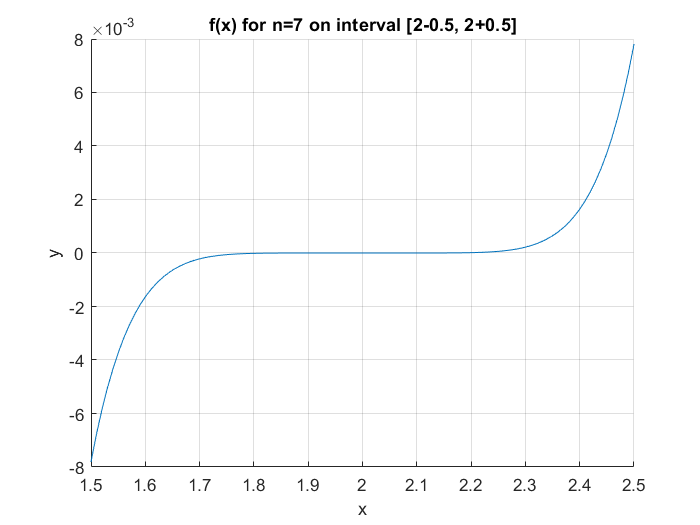

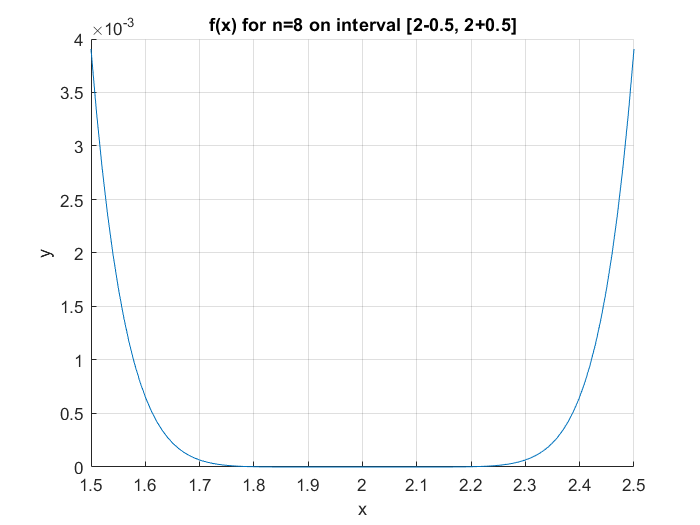

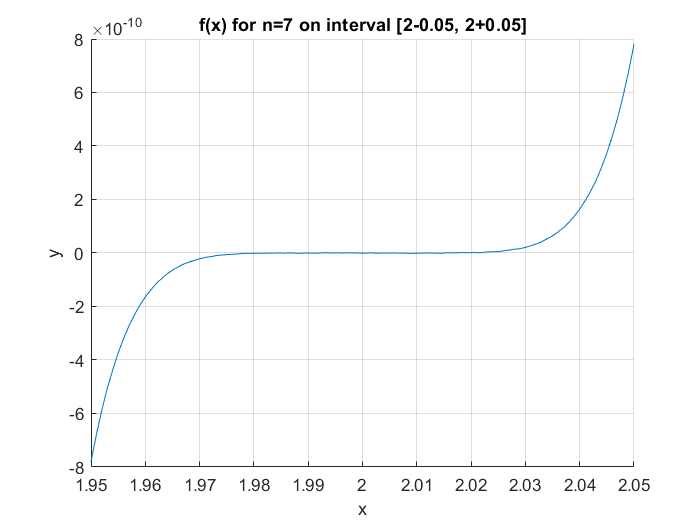

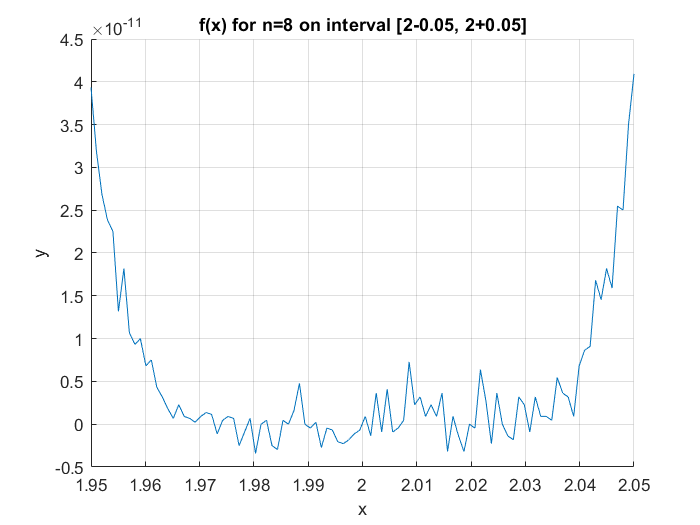

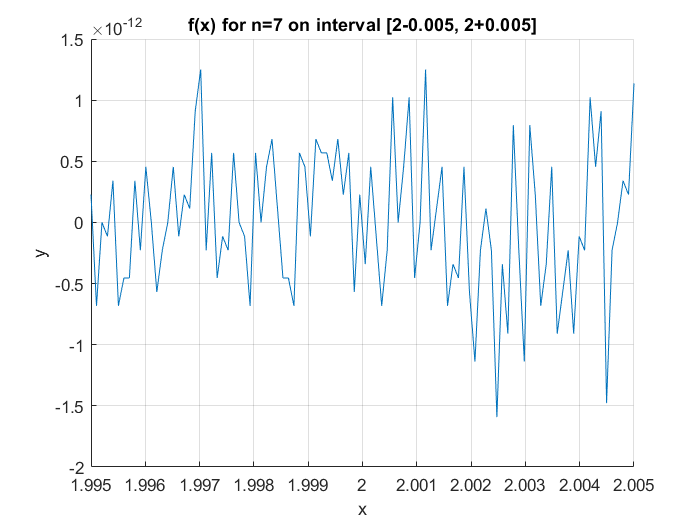

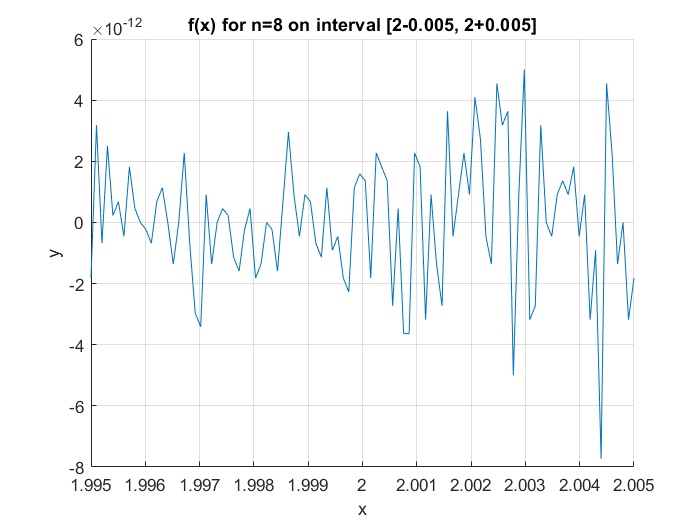

intvs = [.5 .05 .005];
for i = 1:length(intvs)
    x = linspace(2-intvs(i), 2+intvs(i));
    for n = 7:8
        f = 0;
        for k = 0:n
           f=f+nchoosek(n,k)*x.^(n-k)*(-2).^k;
        end
        hold on
        plot(x, f)
        grid on
        xlabel('x'), ylabel('y')
        xlim([2-intvs(i),2+intvs(i)])
        title(['f(x) for n=', num2str(n) ' on interval [2-', num2str(intvs(i)) ', 2+' num2str(intvs(i)) ']']) 
        figure()
    end
end